# EE 146: Computer Vision

# Buddy Ugwumba SID: 862063029

# Lab 5: Corner Detection, Hough Transform

# Date: 02/07/2022

**Goals: **

- **Learn Hough Transform as a voting-based technique for identify objects with a simple parametric model **(Used for gray-scale images)

- **Learn Harris corner detector to compute features.**

**Problem 1: Hough Transform Algorithm**

- Learn Hough Transform algorithm for finding straight lines in images

- Download images having just a few and many lines **(two images)**

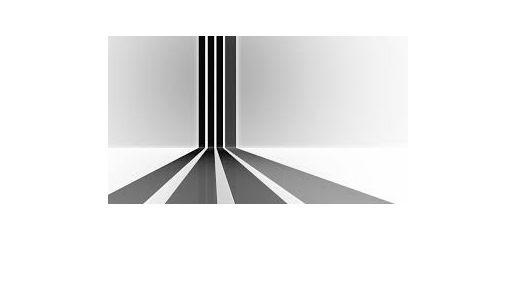

clf
% image of few lines
few_lines = imread('few_lines_2.jpeg');
% Turn the image into a grayscale
few_lines_gray = rgb2gray(few_lines);
imshow(few_lines_gray)

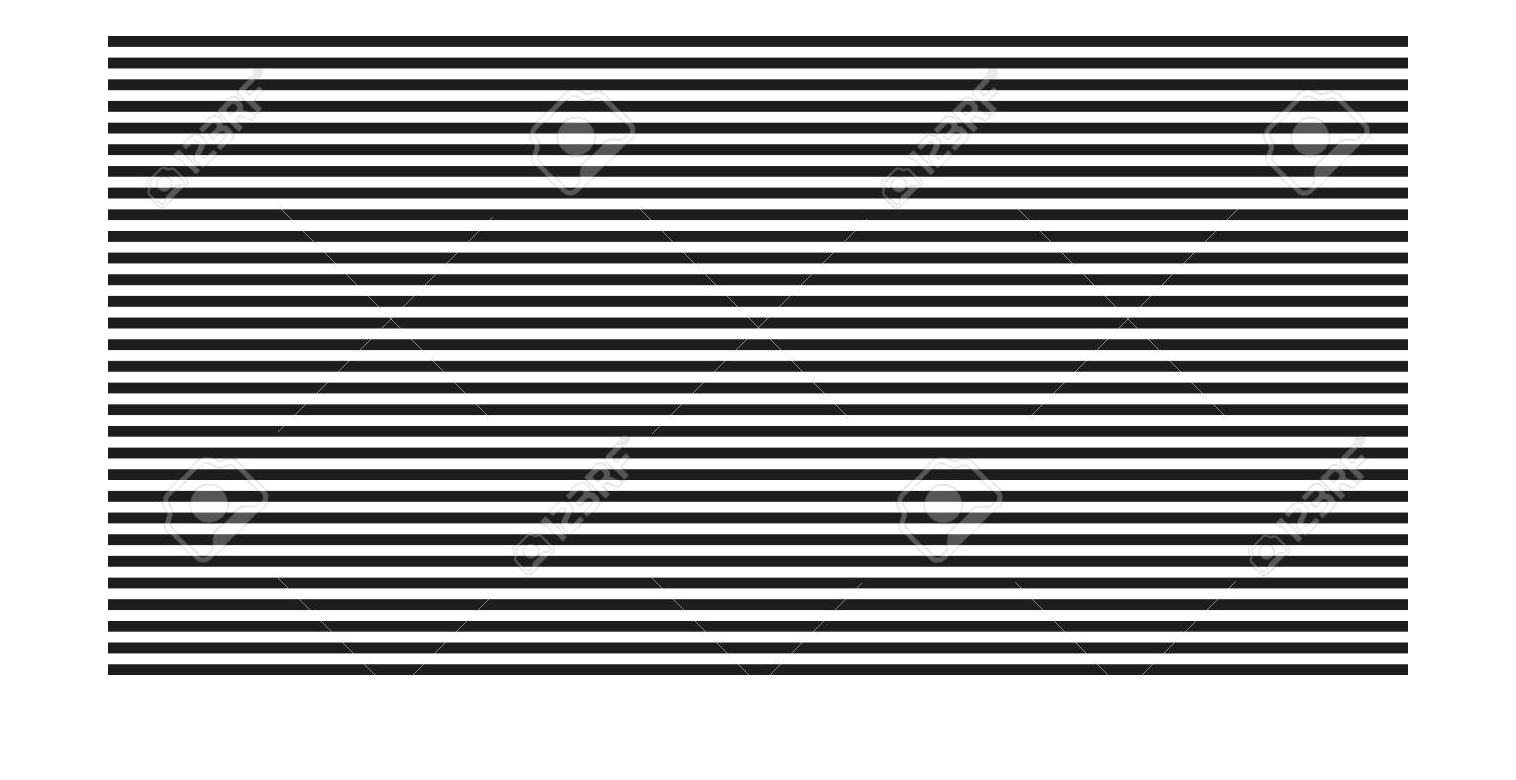

% image of many lines
many_lines = imread('many_lines.jpeg');
% Turn the image into a grayscale
many_lines_gray = rgb2gray(many_lines);
imshow(many_lines_gray);

- Run an edge detector (e.g. Sobel) on these images and threshold the edge magnitude image

few_edge = edge(few_lines_gray, 'Sobel', 0.2);
few_edge1 = edge(few_lines_gray, 'Sobel', 0.02);
many_edge = edge(many_lines_gray, 'Sobel', 0.3);
many_edge1 = edge(many_lines_gray, 'Sobel', 0.03);

- Run Hough transform program on the edge magnitude image with varying thresholds in step 3). 

[H_few1, theta_few1, rho_few1] = hough(few_edge, 'RhoResolution', 0.5, 'Theta', -90:0.5:89);
few_peak1 = houghpeaks(H_few1, 2);
[H_few2, theta_few2, rho_few2] = hough(few_edge1, 'RhoResolution', 0.5, 'Theta', -90:0.5:89);
few_peak2 = houghpeaks(H_few2, 2);
[H_many1, theta_many1, rho_many1] = hough(many_edge, 'RhoResolution', 0.5, 'Theta', -90:0.5:89);
many_peak1 = houghpeaks(H_many1, 2);
[H_many2, theta_many2, rho_many2] = hough(many_edge1, 'RhoResolution', 0.5, 'Theta', -90:0.5:89);
many_peak2 = houghpeaks(H_many2, 2);

- Submit your results and comment on their quality with varying thresholds on the edge magnitude image

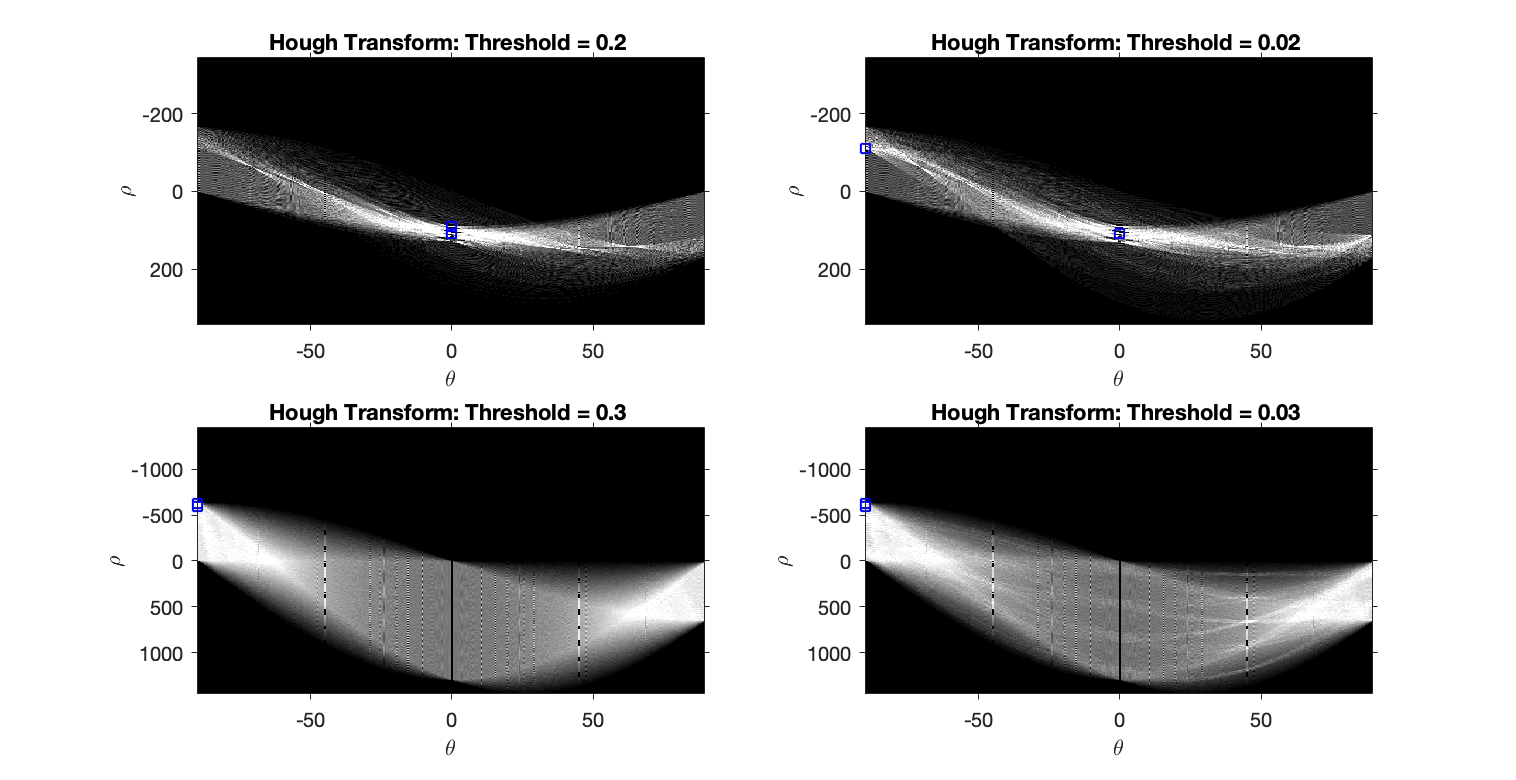

subplot(2,2,1), imshow(imadjust(rescale(H_few1)), 'XData', theta_few1, 'YData', rho_few1, 'InitialMagnification', 'fit');
title("Hough Transform: Threshold = 0.2 ")
xlabel('\theta'), ylabel('\rho'); 
axis on, axis normal, hold on
plot(theta_few1(few_peak1(:,2)), rho_few1(few_peak1(:,1)), 's', 'color', 'blue');

subplot(2,2,2), imshow(imadjust(rescale(H_few2)), 'XData', theta_few2, 'YData', rho_few2, 'InitialMagnification', 'fit');
title("Hough Transform: Threshold = 0.02 ")
xlabel('\theta'), ylabel('\rho'); 
axis on, axis normal, hold on
plot(theta_few1(few_peak2(:,2)), rho_few1(few_peak2(:,1)), 's', 'color', 'blue');

subplot(2,2,3), imshow(imadjust(rescale(H_many1)), 'XData', theta_many1, 'YData', rho_many1, 'InitialMagnification', 'fit');
title("Hough Transform: Threshold = 0.3 ")
xlabel('\theta'), ylabel('\rho'); 
axis on, axis normal, hold on
plot(theta_many1(many_peak1(:,2)), rho_many1(many_peak1(:,1)), 's', 'color', 'blue');

subplot(2,2,4), imshow(imadjust(rescale(H_many2)), 'XData', theta_many2, 'YData', rho_many2, 'InitialMagnification', 'fit');
title("Hough Transform: Threshold = 0.03 ")
xlabel('\theta'), ylabel('\rho'); 
axis on, axis normal, hold on
plot(theta_many2(many_peak2(:,2)), rho_many2(many_peak2(:,1)), 's', 'color', 'blue');

- Were you able to extract co-libear lines, parallel lines?

- What is the length of the shortest and longest line that you were able to detect.

**Problem 2: Harris Corner Detector**

- Download Images from ilearn

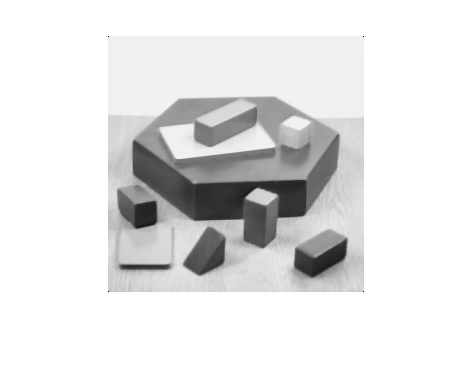

figure
shapesCorner = imread("shapesCorner.tiff");
imshow(shapesCorner)

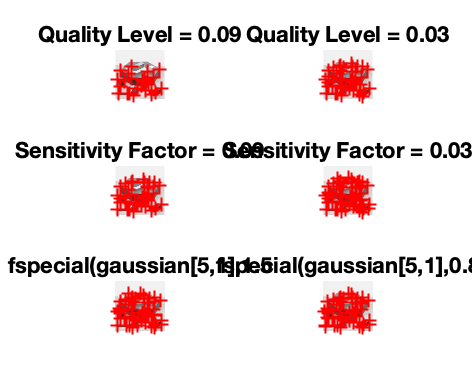

subplot(3,2,1)
C = corner(shapesCorner, 'QualityLevel', 0.18);
imshow(shapesCorner), title("Quality Level = 0.18")
hold on
plot(C(:,1), C(:,2), 'r+')

subplot(3,2,2)
C2 = corner(shapesCorner, 'QualityLevel', 0.06);
imshow(shapesCorner), title("Quality Level = 0.06")
hold on
plot(C2(:,1), C2(:,2), 'r+')

subplot(3,2,3)
C3 = corner(shapesCorner, 'SensitivityFactor', 0.18);
imshow(shapesCorner), title("Sensitivity Factor = 0.18")
hold on
plot(C3(:,1), C3(:,2), 'r+')

subplot(3,2,4)
C4 = corner(shapesCorner, 'SensitivityFactor', 0.06);
imshow(shapesCorner), title("Sensitivity Factor = 0.06")
hold on
plot(C4(:,1), C4(:,2), 'r+')

subplot(3,2,5)
C5 = corner(shapesCorner, 'FilterCoefficients', fspecial....
    ('gaussian', [5,1],1.5));
imshow(shapesCorner), title("fspecial(gaussian[5,1],1.5")
hold on
plot(C5(:,1), C5(:,2), 'r+')

subplot(3,2,6)
C6 = corner(shapesCorner, 'FilterCoefficients', fspecial....
    ('gaussian', [5,1],0.8));
imshow(shapesCorner), title("fspecial(gaussian[5,1],0.8")
hold on
plot(C6(:,1), C6(:,2), 'r+')

2. Understand Harris Corner detector and run it on selected images in 1

3. Experiement with various parameters: control parameter, response threshold, and neighborhood radius

4. Evaluate the performacne of paramters in 3) and report their individual effects on images selected in 1)